# Risposte di Funzioni Di Trasferimento (FDT)

## Setup

close all;
clear all;
clc;
FS = 18; % FontSize
LW = 2; % LineWidth

## Variabili simboliche

syms Yel(s)
syms yel(t)

## Esempio

Asse del tempo

tt = linspace(0, 10, 1000);

### Esercizio 2.11.1

#### FDT

G = tf([9 1], [2 3 2])

G =
 
      9 s + 1
  ---------------
  2 s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


#### Modello del sistema

[A,B,C,D] = tf2ss(G.Numerator{1}, G.Denominator{1})

A =    -1.5000   -1.0000
    1.0000         0


B =      1
     0


C =     4.5000    0.5000


D = 0

#### Autovalori

eig(A)

ans =   -0.7500 + 0.6614i
  -0.7500 - 0.6614i


#### Evoluzione libera

Trasformata

Yel(s) = simplify(free_evolution(A, C, ones(size(C))'));
pretty(Yel)

   20 s - 13
--------------
   2
4 s  + 6 s + 4



Evoluzione libera nel dominio del tempo

yel(t) = simplify(ilaplace(Yel));
pretty(vpa(yel, 4))

exp(-0.75 t) (cos(0.6614 t) - sin(0.6614 t) 2.117) 5.0



#### Grafico

Evoluzione libera

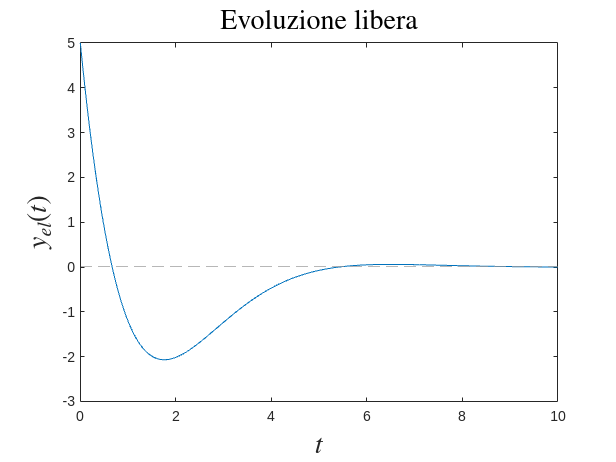

figure(Name='Evoluzione libera')
plot(tt, yel(tt))
xlim([tt(1) tt(end)])
xlabel('$$t$$', Interpreter='latex', FontSize=20)
ylabel('$$y_{el}(t)$$', Interpreter='latex', FontSize=20)
yline(double(yel(tt(end))), '--', LineWidth=0.5, Color=[0.6 0.6 0.6])
title("Evoluzione libera", Interpreter='latex', FontSize=20)

Risposta al gradino

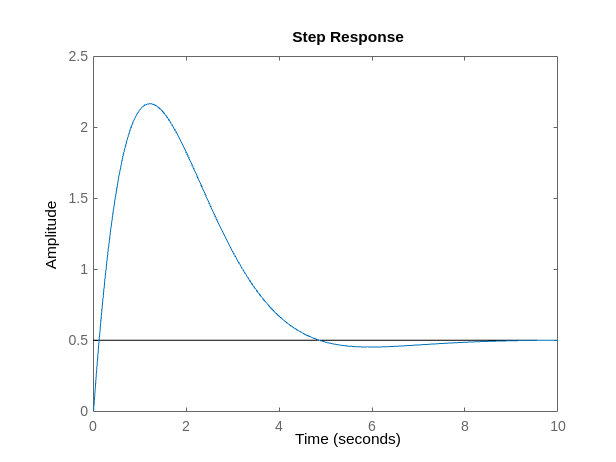

figure(Name='Risposta al gradino')
step(G)

### G1

#### Funzione di trasferimento

G1 = zpk([], [-2], 10)

G1 =
 
   10
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


G1 = tf(G1)

G1 =
 
   10
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

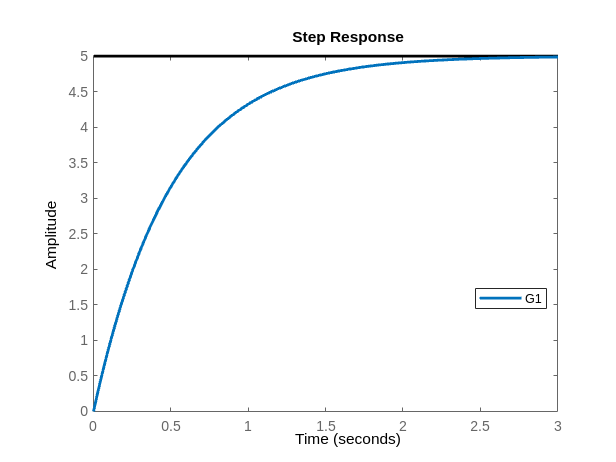

figure(Name='G1')
step(G1)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### G2

#### Funzione di trasferimento

G2 = zpk([], [-2, -10-10j, -10+10j], 2000)

G2 =
 
           2000
  -----------------------
  (s+2) (s^2 + 20s + 200)
 
Continuous-time zero/pole/gain model.
Model Properties


G2 = tf(G2)

G2 =
 
             2000
  --------------------------
  s^3 + 22 s^2 + 240 s + 400
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

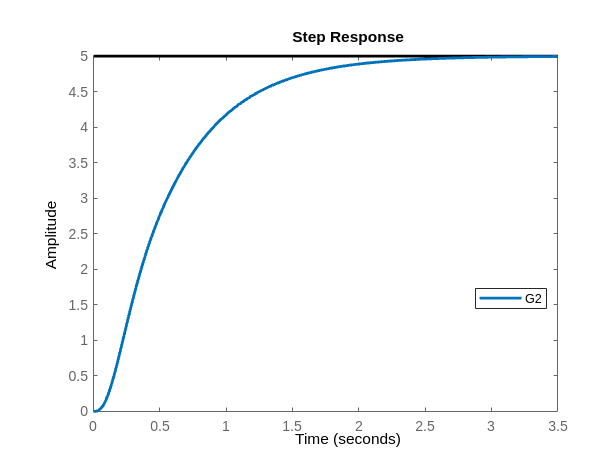

figure(Name='G2')
step(G2)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Pproperty='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### G3

#### Funzione di trasferimento

G3 = zpk([], [-2, -2-2j, -2+2j], 80)

G3 =
 
           80
  --------------------
  (s+2) (s^2 + 4s + 8)
 
Continuous-time zero/pole/gain model.
Model Properties


G3 = tf(G3)

G3 =
 
            80
  -----------------------
  s^3 + 6 s^2 + 16 s + 16
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

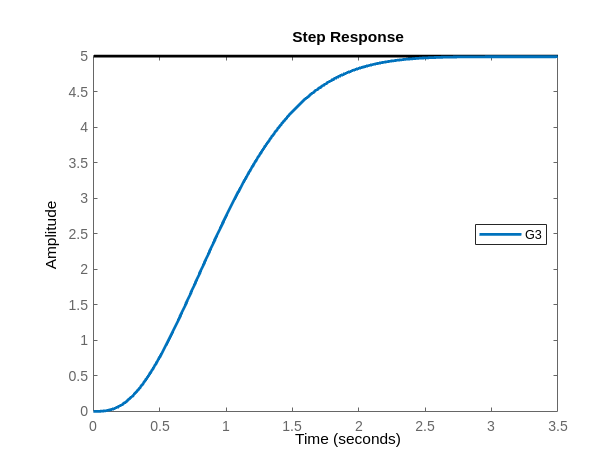

figure(Name='G3')
step(G3)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### G4

#### Funzione di trasferimento

G4 = zpk([], [-2, -2-20j, -2+20j], 4040)

G4 =
 
           4040
  ----------------------
  (s+2) (s^2 + 4s + 404)
 
Continuous-time zero/pole/gain model.
Model Properties


G4 = tf(G4)

G4 =
 
            4040
  -------------------------
  s^3 + 6 s^2 + 412 s + 808
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

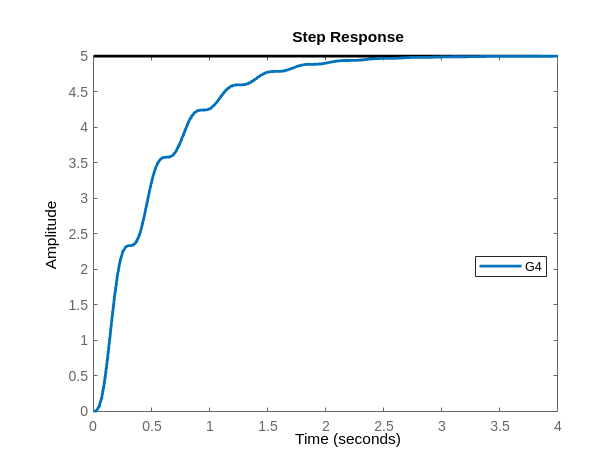

figure(Name='G4')
step(G4)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### G5

#### Funzione di trasferimento

G5 = zpk([], [-10, -2-20j, -2+20j], 20200)

G5 =
 
           20200
  -----------------------
  (s+10) (s^2 + 4s + 404)
 
Continuous-time zero/pole/gain model.
Model Properties


G5 = tf(G5)

G5 =
 
             20200
  ---------------------------
  s^3 + 14 s^2 + 444 s + 4040
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

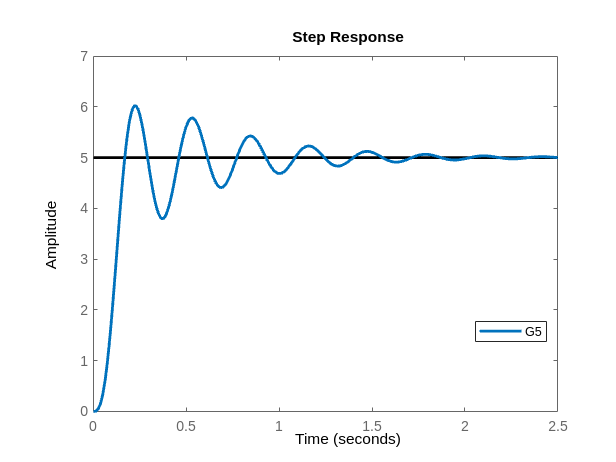

figure(Name='G5')
step(G5)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### H1

#### Funzione di trasferimento

H1 = zpk([], [-2, -10-100j, -10+100j], 101000)

H1 =
 
           1.01e+05
  ---------------------------
  (s+2) (s^2 + 20s + 1.01e04)
 
Continuous-time zero/pole/gain model.
Model Properties


H1 = tf(H1)

H1 =
 
              101000
  ------------------------------
  s^3 + 22 s^2 + 10140 s + 20200
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

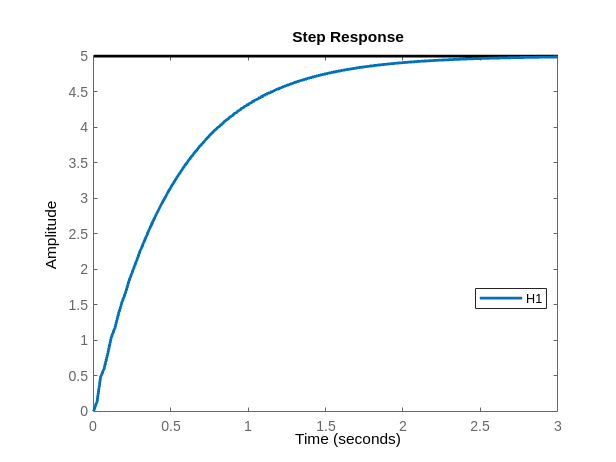

figure(Name='H1')
step(H1)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### H2

#### Funzione di trasferimento

H2 = zpk([-1.9], [-2, -10-100j, -10+100j], 101000/1.9)

H2 =
 
         53158 (s+1.9)
  ---------------------------
  (s+2) (s^2 + 20s + 1.01e04)
 
Continuous-time zero/pole/gain model.
Model Properties


H2 = tf(H2)

H2 =
 
       5.316e04 s + 101000
  ------------------------------
  s^3 + 22 s^2 + 10140 s + 20200
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

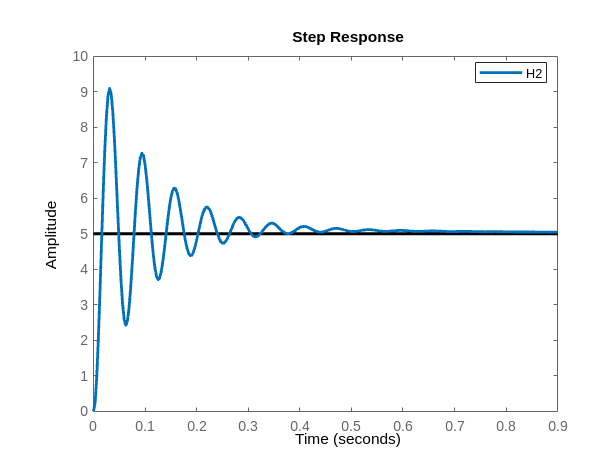

figure(Name='H2')
step(H2)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### H3

#### Funzione di trasferimento

H3 = zpk([-5], [-2, -10-100j, -10+100j], 20200)

H3 =
 
          20200 (s+5)
  ---------------------------
  (s+2) (s^2 + 20s + 1.01e04)
 
Continuous-time zero/pole/gain model.
Model Properties


H3 = tf(H3)

H3 =
 
         20200 s + 101000
  ------------------------------
  s^3 + 22 s^2 + 10140 s + 20200
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

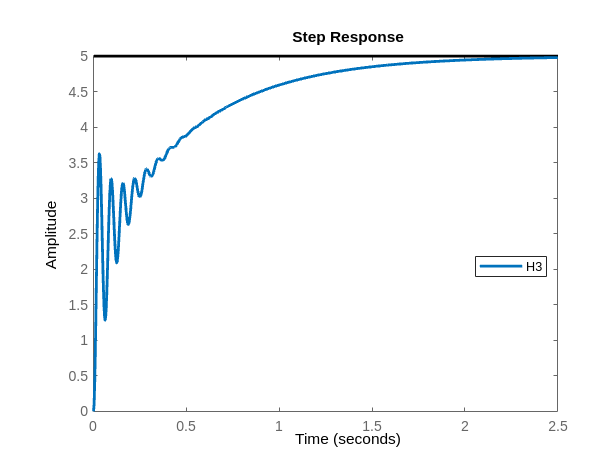

figure(Name='H3')
step(H3)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

### H4

#### Funzione di trasferimento

H4 = zpk([2], [-2, -10-100j, -10+100j], -50500)

H4 =
 
         -50500 (s-2)
  ---------------------------
  (s+2) (s^2 + 20s + 1.01e04)
 
Continuous-time zero/pole/gain model.
Model Properties


H4 = tf(H4)

H4 =
 
        -50500 s + 101000
  ------------------------------
  s^3 + 22 s^2 + 10140 s + 20200
 
Continuous-time transfer function.
Model Properties


#### Risposta al gradino

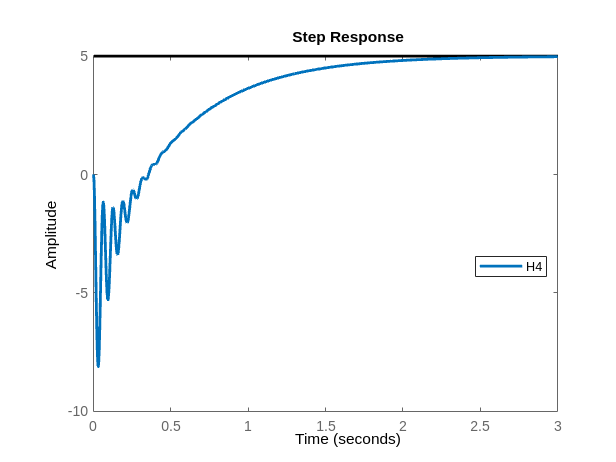

figure(Name='H4')
step(H4)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

## Compare different plots

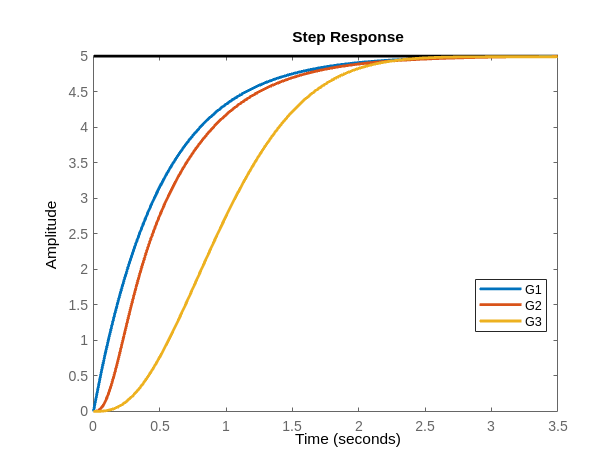

step(G1, G2, G3)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

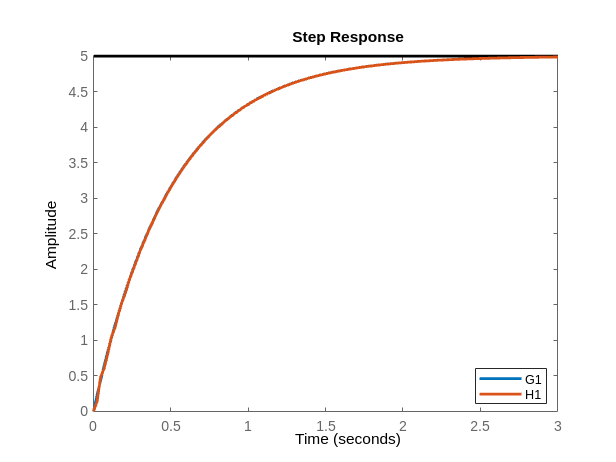

step(G1, H1)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)

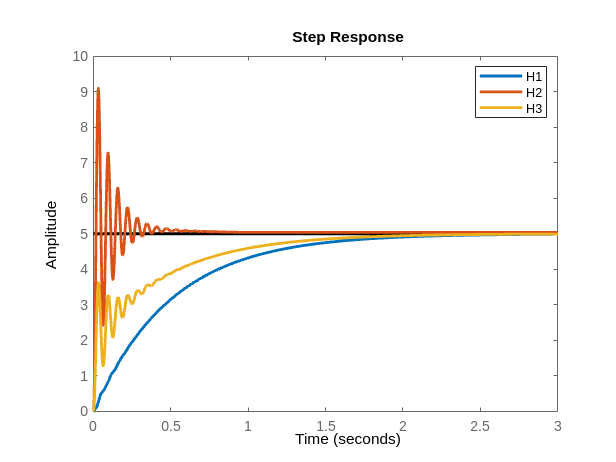

step(H1, H2, H3)
[~, lgd, ~, ~] = legend(Location='best');
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)